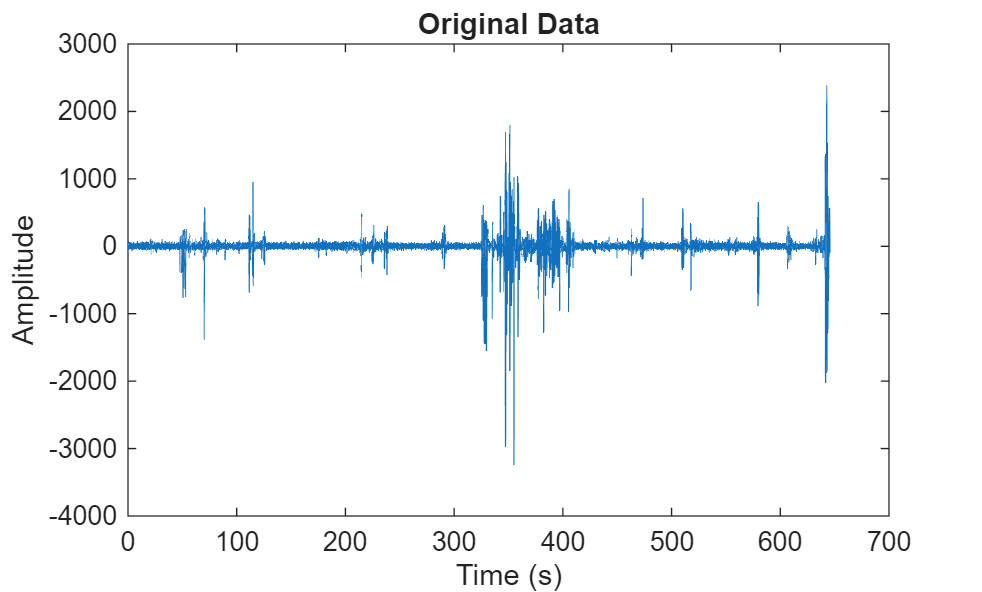

clear;
rng(42)
    
dataStruct = readmatrix("\\wsl.localhost\Ubuntu\home\merlijn\projects\brain_computer_project\Ass2\recorded_data\group3.txt");

%omit column 10
raw_time = dataStruct(:, 1);
raw_data = dataStruct(:, 4); %Select only Cz
raw_labels = dataStruct(:, 11);

idx = find(raw_labels == 1, 1, 'first');
data = raw_data(idx:end, :);
time = raw_time(idx:end, :);
time = time - time(1);
labels = raw_labels(idx:end, :);

nr_labels = sum(labels);


numChannels = size(data,2);

figure
plot(time, data)
title('Original Data')
%ylim([-1.5 1.5])
xlabel('Time (s)')
ylabel('Amplitude')

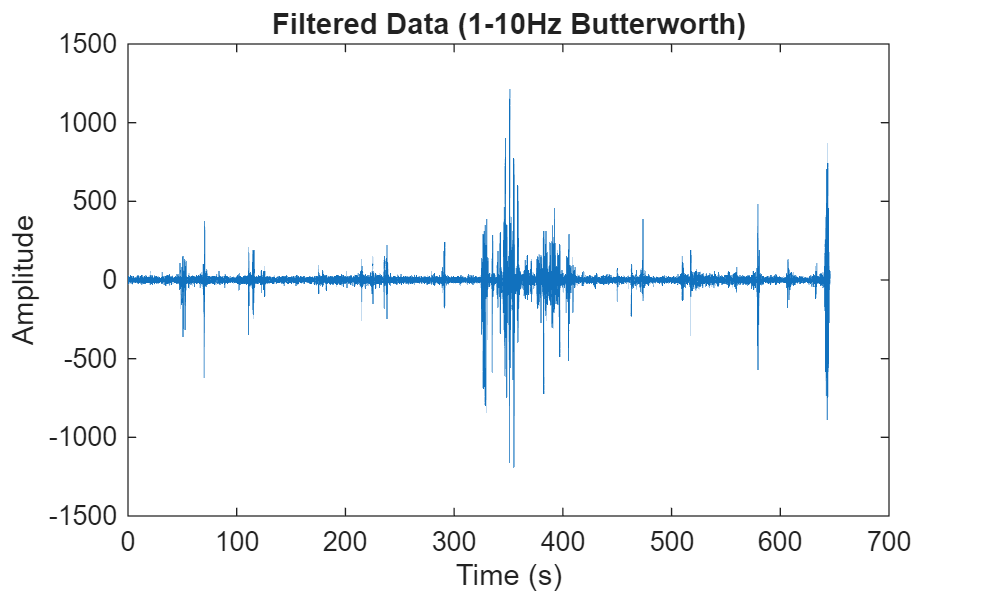


%bandpass the data
%m = n = 4 for bandpass and bandstop filters.
%https://nl.mathworks.com/help/signal/ref/butter.html
fs = 250; % Sampling frequency
lowCutoff = 2.5; % Low cutoff frequency
highCutoff = 13; % High cutoff frequency
[b, a] = butter(4, [lowCutoff, highCutoff] / (fs / 2), 'bandpass');

% Apply the bandpass filter to the data
filteredData = filtfilt(b, a, data);

figure
plot(time, filteredData)
title('Filtered Data (1-10Hz Butterworth)')
%ylim([-1.5 1.5])
xlabel('Time (s)')
ylabel('Amplitude')

%Average 2 consecutive timepoints. -> donwsample to 125hz
windowSize = 2

windowSize = 2

fs = 250/windowSize

fs = 125

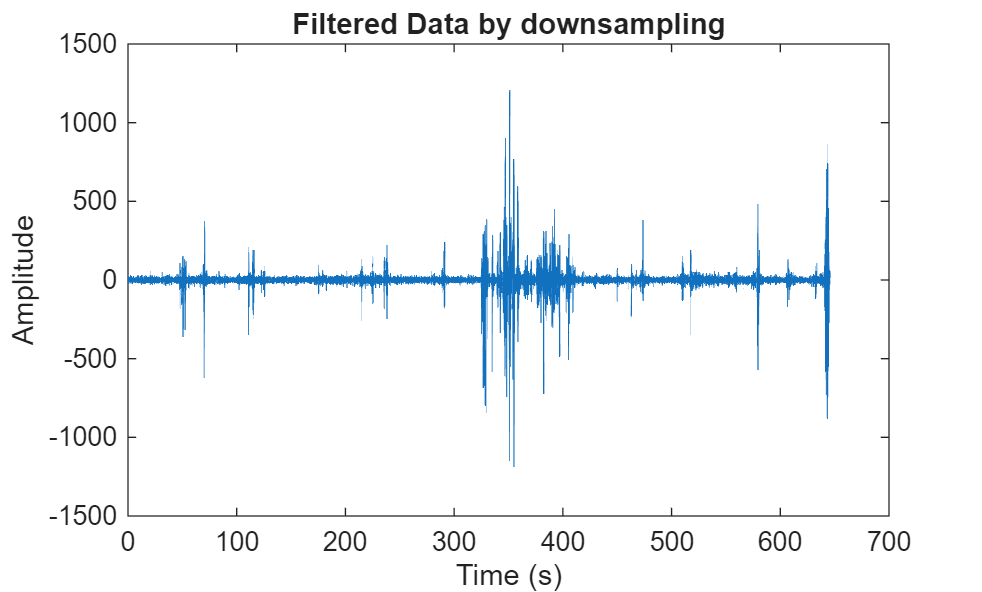


n_windows = floor(size(filteredData, 1)/windowSize);
dataTrimmed = filteredData(1:n_windows*windowSize, :);
reshaped = reshape(dataTrimmed, windowSize, n_windows, []);
avgData = squeeze(mean(reshaped, 1))';

timeTrimmed = time(1:n_windows*windowSize);
timeReshaped = reshape(timeTrimmed, windowSize, n_windows);
avgTime = mean(timeReshaped, 1)';

labelsTrimmed = labels(1:n_windows*windowSize);
labelsReshaped = reshape(labelsTrimmed, windowSize, n_windows);
avgLabels = any(labelsReshaped, 1)';

figure
plot(avgTime, avgData)
title('Filtered Data by downsampling')
%ylim([-1.5 1.5])
xlabel('Time (s)')
ylabel('Amplitude')

time = linspace(0,646,size(avgData, 1));
artifact_idx1 = find(time >= 320, 1, 'first');
artifact_idx2 = find(time >= 420, 1, 'first');

range1 = avgLabels(1:artifact_idx1, :);
range2 = avgLabels(artifact_idx2:end, :);

artifact_idx1 = find(range1 == 1, 1, 'last');
artifact_idx2_ofsset = find(range2 == 1, 1, 'first');
artifact_idx2 = artifact_idx2 + artifact_idx2_ofsset -1

artifact_idx2 = 52494


badstart = artifact_idx1 + round(0.8*fs);
badend = artifact_idx2;

artifact_mask = false(size(avgData, 1), 1);
artifact_mask(badstart:badend) = true;

avgData(artifact_mask) = mean(avgData);

artifact_idx = find(avgLabels == 1, 1, 'last');
last_idx = round(fs * 0.8) + artifact_idx

last_idx = 78691

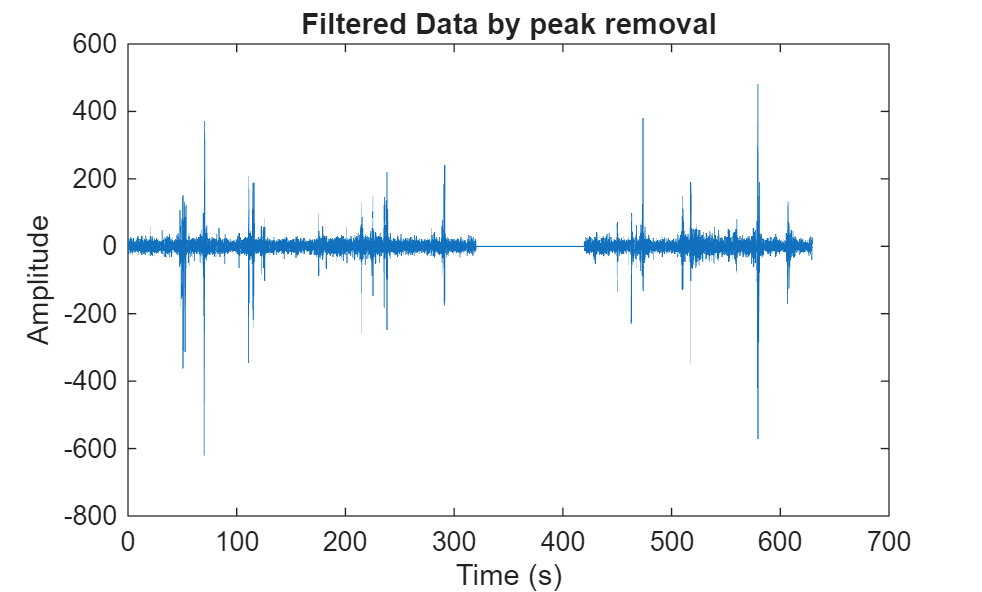


avgData = avgData(1:last_idx);
avgTime = avgTime(1:last_idx);
avgLabels = avgLabels(1:last_idx);

figure
plot(avgTime, avgData)
title('Filtered Data by peak removal')
%ylim([-1.5 1.5])
xlabel('Time (s)')
ylabel('Amplitude')

%Create the trials of target and non-target.
epoch_length = 0.8;
sample_length = round(fs * epoch_length);

N = size(avgData, 1);
C = size(avgData, 2);

targetTrials_idx = find(avgLabels == 1);
nonTargetTrials_idx = find(avgLabels == 0);

targetTrials = zeros(length(targetTrials_idx), sample_length, C);
isTargetWindow = false(N,1);
count = 0;

for i=1:length(targetTrials_idx)
    start_idx = targetTrials_idx(i);
    end_idx = min(start_idx + sample_length - 1, N);
    if any(artifact_mask(start_idx:end_idx))
        continue
    end
    count = count +1;
    targetTrials(i, :, :) = avgData(start_idx:end_idx, :);
    isTargetWindow(start_idx:end_idx) = true;
end

targetTrials = targetTrials(1:count,:,:);

nonTargetTrials = zeros(length(nonTargetTrials_idx), sample_length, C);
count = 0;

for i=1:length(nonTargetTrials_idx)
    start_idx = nonTargetTrials_idx(i);
    end_idx = start_idx + sample_length - 1;
    if any(artifact_mask(start_idx:end_idx))
        continue
    end
    if end_idx >= N - 2 * fs
        %Do not take from last 2 seconds as this is towards the end
        break
    end
    if all(~isTargetWindow(start_idx:end_idx))
        count = count + 1;
        nonTargetTrials(count, :, :) = avgData(start_idx:end_idx, :);
    end
end

nonTargetTrials = nonTargetTrials(1:count,:,:);


% Shuffle the trials to ensure randomization
non_s = size(nonTargetTrials, 1);
target_s = size(targetTrials, 1);

non_r = randperm(non_s);
target_r = randperm(target_s);

targetTrials = targetTrials(target_r, :);
nonTargetTrials = nonTargetTrials(non_r, :);

train_target = targetTrials(1:147, :);
test_target = targetTrials(148:293, :);

n_nontarget = round(147/200 * 900);
train_nonTarget = nonTargetTrials(1:n_nontarget, :);
test_nonTarget = nonTargetTrials(n_nontarget+1:n_nontarget*2, :);

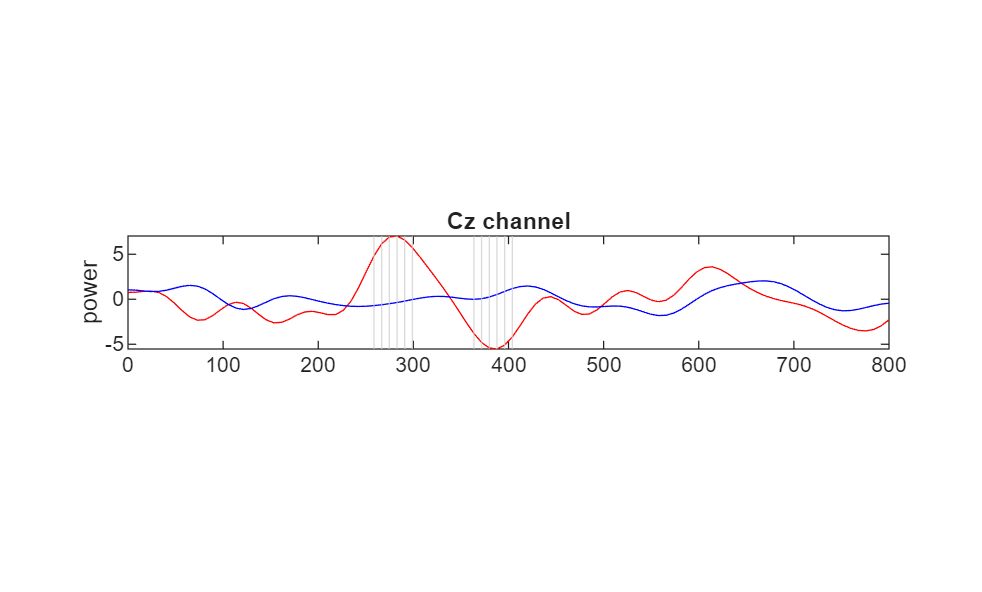

Cz_mean_non_tar = mean(train_nonTarget, 1);
Cz_mean_tar = mean(train_target, 1);

function [diff,p_values] = stat_diff(tar, non_tar)
    num_timesteps = size(tar, 2);
    diff = zeros(num_timesteps, 1);
    p_values = zeros(num_timesteps, 1);

    for i = 1:num_timesteps
        time_tar = tar(:, i);
        time_non = non_tar(:, i);
        
        [p, h] = ranksum(time_tar(:), time_non(:), 'alpha', (0.01/num_timesteps)); %Bonferroni correction
        
        % we store a list that has a 1 if a timestep was significantly
        % differena and 0 if it was not
        diff(i) = h;
        p_values(i) = p;
    end
end

[Cz_stats, Cz_ps] = stat_diff(train_target, train_nonTarget);

function plot_stats(stats, t)
    % whenever the stats are 1 (significant), we take that specific time,
    % measured in seconds, so it can be plotted
    sig_times = t(stats == 1);
    
    if ~isempty(sig_times)
        xline(sig_times, 'Color', [0.8 0.8 0.8], 'HandleVisibility', 'off');
    end
end

t = linspace(0, 800, 100);
figure;

subplot(3, 1, 2);
plot(t, Cz_mean_tar, 'r');
hold on
plot(t, Cz_mean_non_tar, 'b');
hold on
plot_stats(Cz_stats, t)
hold off
title('Cz channel')
ylabel('power')

[M_1, I_1] = min(Cz_ps(33:37)) % index 35

M_1 = 3.2852e-11

I_1 = 3

[M_2, I_2] = min(Cz_ps(48:50)) % index 49

M_2 = 2.6816e-09

I_2 = 1

train_nontarget_dimA = train_nonTarget(:,35);
train_target_dimA = train_target(:,35);
train_nontarget_dimB = train_nonTarget(:,49);
train_target_dimB = train_target(:,49);

test_nontarget_dimA = test_nonTarget(:,35);
test_target_dimA = test_target(:,35);
test_nontarget_dimB = test_nonTarget(:,49);
test_target_dimB = test_target(:,49);

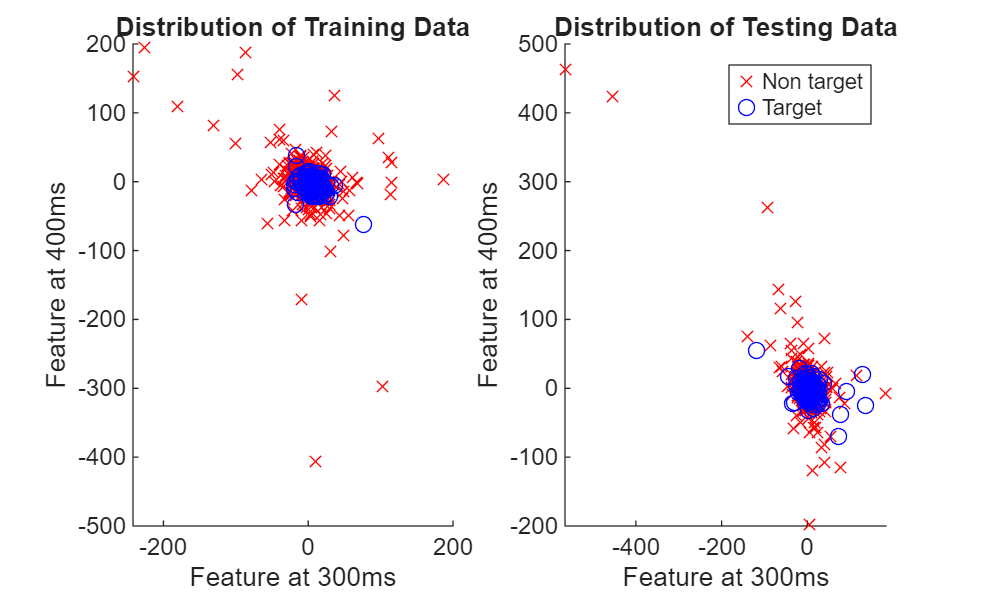

% Plot training data
figure;
subplot(1,2,1);
scatter(train_nontarget_dimA(:), train_nontarget_dimB(:), 'red', 'x', 'MarkerFaceAlpha', 0.5);
hold on;
scatter(train_target_dimA(:), train_target_dimB(:), 'blue', 'o', 'MarkerFaceAlpha', 0.5);
hold off;

title('Distribution of Training Data');
xlabel('Feature at 300ms');
ylabel('Feature at 400ms');

% Plot test data
subplot(1,2,2);
scatter(test_nontarget_dimA(:), test_nontarget_dimB(:), 'red', 'x', 'MarkerFaceAlpha', 0.5);
hold on;
scatter(test_target_dimA(:), test_target_dimB(:), 'blue', 'o', 'MarkerFaceAlpha', 0.5);
hold off;

title('Distribution of Testing Data');
legend('Non target', 'Target');
xlabel('Feature at 300ms');
ylabel('Feature at 400ms');

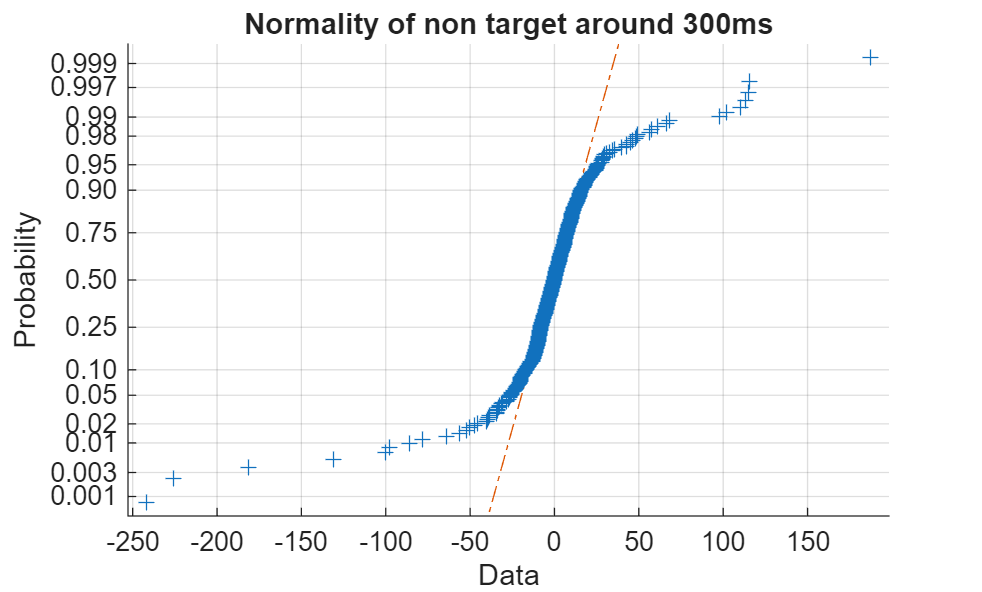

figure;

normplot(train_nontarget_dimA(:))
title('Normality of non target around 300ms');

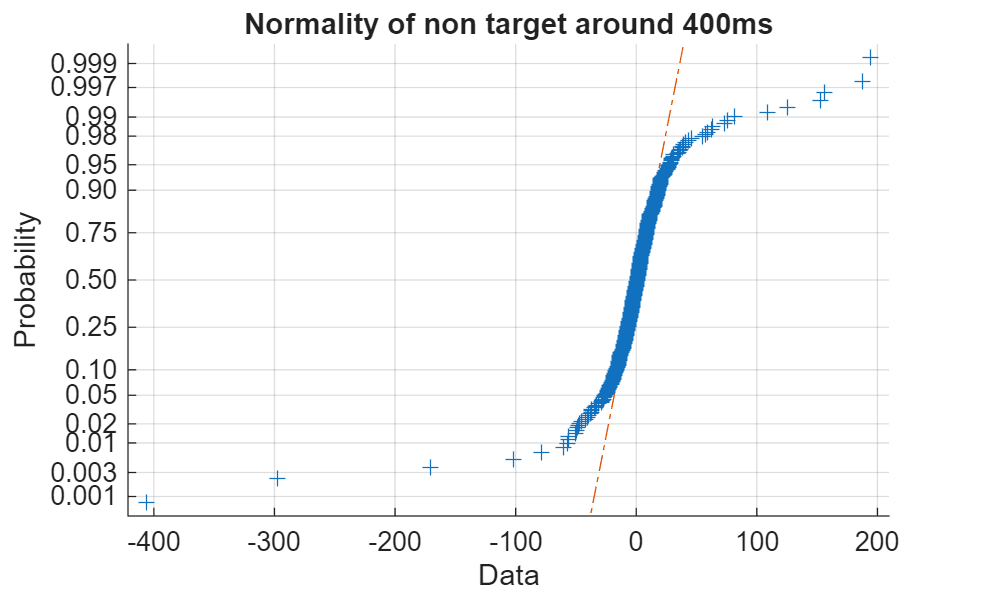


normplot(train_nontarget_dimB(:))
title('Normality of non target around 400ms');

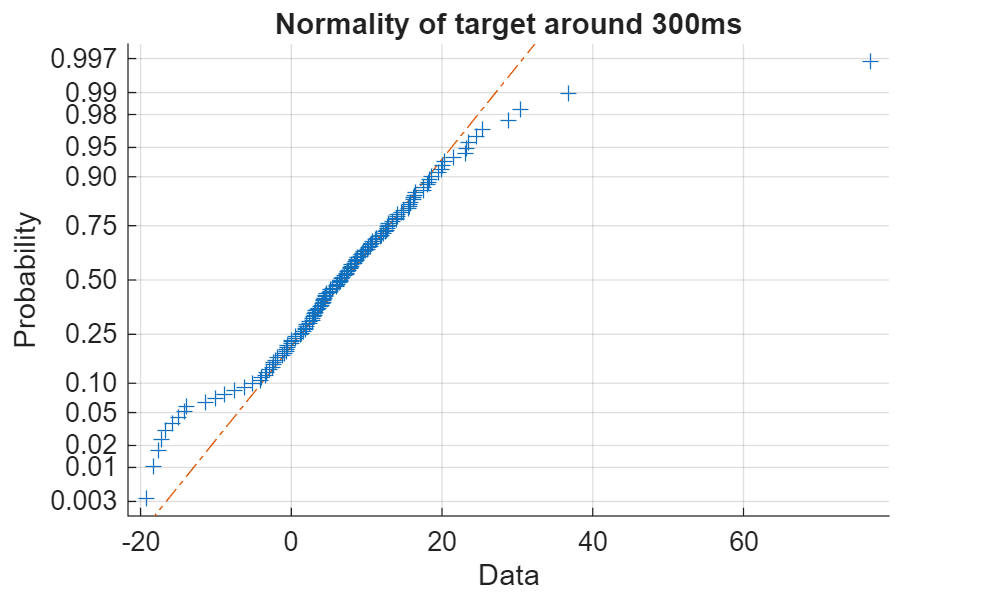


normplot(train_target_dimA(:))
title('Normality of target around 300ms');

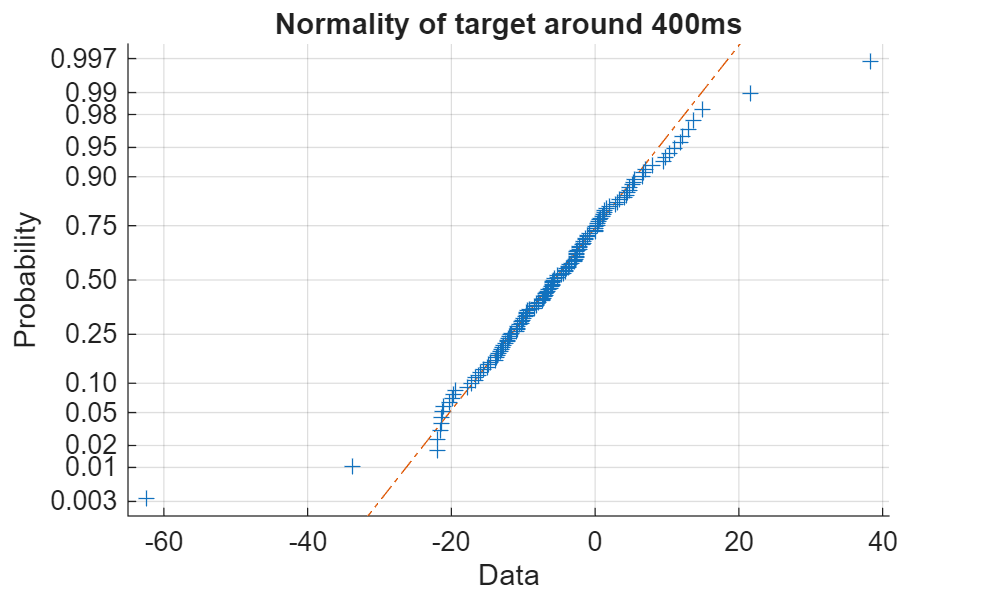


normplot(train_target_dimB(:))
title('Normality of target around 400ms');

X_train_non = [train_nontarget_dimA(:), train_nontarget_dimB(:)];
X_train_tar = [train_target_dimA(:), train_target_dimB(:)];
X_train = cat(1, X_train_non, X_train_tar);
Y_train = cat(1, -1*ones(size(train_nontarget_dimA(:))), ones(size(train_target_dimA(:)))); % Labels for training data

X_test_non = [test_nontarget_dimA(:), test_nontarget_dimB(:)];
X_test_tar = [test_target_dimA(:), test_target_dimB(:)];
X_test = cat(1, X_test_non, X_test_tar);
Y_test = cat(1, -1*ones(size(test_nontarget_dimA(:))), ones(size(test_target_dimA(:)))); % Labels for testing data

[acc_train, acc_test, w, b, line] = custom_LDA(X_train', Y_train', X_test', Y_test');

Test Set Accuracy: 81.93%
Train Set Accuracy: 81.46%


result = sign(w' * X_test' + b);
results_c1 = result(Y_test == -1);
results_c2 = result(Y_test == 1);
correct_c1 = (results_c1 == -1);
correct_c2 = (results_c2 == 1);

accuracy_c1 = sum(correct_c1) / length(results_c1)

accuracy_c1 = 0.9985

accuracy_c2 = sum(correct_c2) / length(results_c2)

accuracy_c2 = 0.0068

accuracy = accuracy_c1 * 0.5 + accuracy_c2 * 0.5

accuracy = 0.5027


fprintf('Balanced test Set Accuracy: %.2f%%\n', accuracy * 100);

Balanced test Set Accuracy: 50.27%


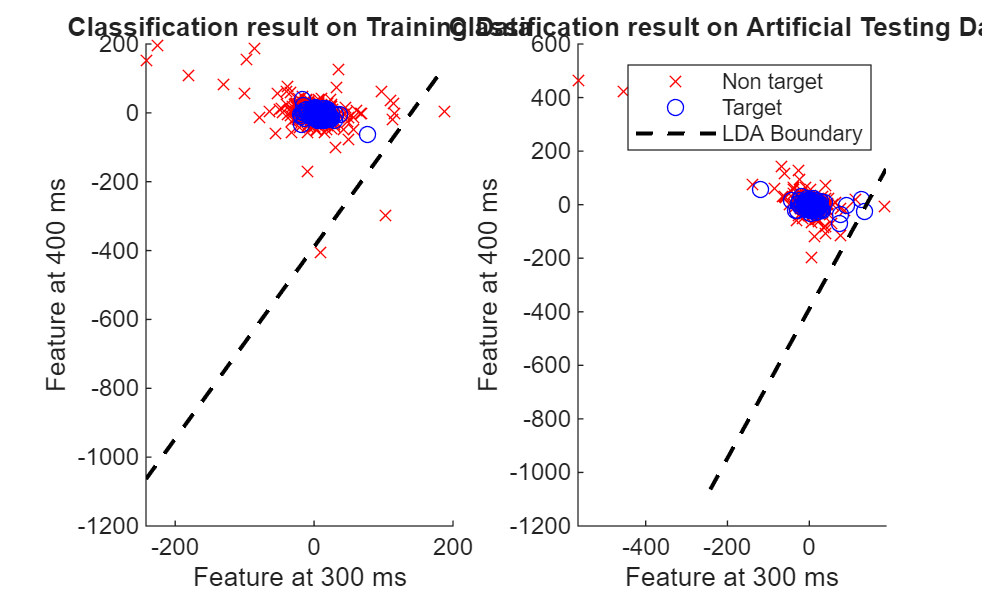

% Plot resutls
% Plot training data
figure;
subplot(1,2,1);
scatter(train_nontarget_dimA(:), train_nontarget_dimB(:), 'red', 'x', 'MarkerFaceAlpha', 0.5);
hold on;
scatter(train_target_dimA(:), train_target_dimB(:), 'blue', 'o', 'MarkerFaceAlpha', 0.5);
plot(line.x, line.y, '--k', 'LineWidth', 1.5);
hold off;

title('Classification result on Training Data');
xlabel('Feature at 300 ms');
ylabel('Feature at 400 ms');

% Plot test data
subplot(1,2,2);
scatter(test_nontarget_dimA(:), test_nontarget_dimB(:), 'red', 'x', 'MarkerFaceAlpha', 0.5);
hold on;
scatter(test_target_dimA(:), test_target_dimB(:), 'blue', 'o', 'MarkerFaceAlpha', 0.5);
plot(line.x, line.y, '--k', 'LineWidth', 1.5);
hold off;

title('Classification result on Artificial Testing Data');
legend('Non target', 'Target', 'LDA Boundary');
xlabel('Feature at 300 ms');
ylabel('Feature at 400 ms');